Problem 1: Basic Plant Response Analysis

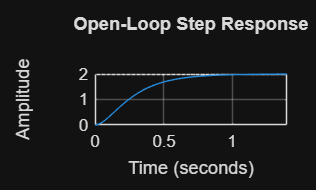

% Define the plant G(s)
s = tf('s');
G = 100 / (s^2 + 15*s + 50);

% -- Task (a): Open-Loop Analysis --
figure;
step(G);
title('Open-Loop Step Response');
grid on;


% Calculate metrics
info_open = stepinfo(G);
disp('Open-Loop Metrics:');

Open-Loop Metrics:


disp(['Rise Time: ', num2str(info_open.RiseTime)]);

Rise Time: 0.51802


disp(['Settling Time: ', num2str(info_open.SettlingTime)]);

Settling Time: 0.92005


disp(['Overshoot: ', num2str(info_open.Overshoot)]);

Overshoot: 0



% Calculate Steady State Error for Step Input (Reference = 1)
% DC Gain = Limit as s->0 of G(s) = 100/50 = 2
dc_gain = dcgain(G);
ess_open = abs(1 - dc_gain); % Assuming unit step input
disp(['Steady-State Error (Open Loop): ', num2str(ess_open)]);

Steady-State Error (Open Loop): 1


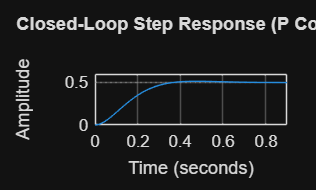


% -- Task (b): P Controller Design --
Kp_p = 0.5;
C_p = Kp_p;
Sys_p = feedback(C_p*G, 1);

figure;
step(Sys_p);
title('Closed-Loop Step Response (P Control)');
grid on;


info_p = stepinfo(Sys_p);
ess_p = abs(1 - dcgain(Sys_p));
disp(['Steady-State Error (P Control): ', num2str(ess_p)]);

Steady-State Error (P Control): 0.5


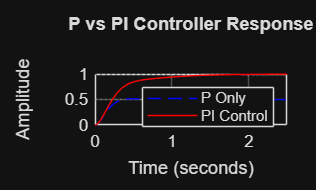


% -- Task (c): PI Controller Design --
Kp_pi = 0.5;
Ki_pi = 1.5;
C_pi = Kp_pi + Ki_pi/s;
Sys_pi = feedback(C_pi*G, 1);

figure;
step(Sys_p, 'b--', Sys_pi, 'r');
legend('P Only', 'PI Control');
title('P vs PI Controller Response');
grid on;


info_pi = stepinfo(Sys_pi);
disp('PI Control Metrics:');

PI Control Metrics:


disp(info_pi);

         RiseTime: 0.6278
    TransientTime: 1.5377
     SettlingTime: 1.5377
      SettlingMin: 0.9016
      SettlingMax: 0.9981
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9981
         PeakTime: 2.6861



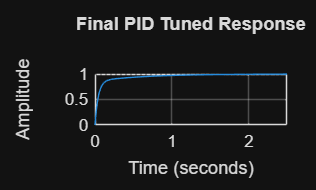


% -- Task (d): PID Controller Tuning --
% Using pidtune to find gains that meet: OS < 10%, Ts < 2s
opts = pidtuneOptions('DesignFocus', 'reference-tracking');
[C_pid, info_tune] = pidtune(G, 'pid', opts);

% Setup Manual Gains if pidtune not available or to force specs:
% Example tuned values (you can adjust these manually):
Kp_final = 2.5; 
Ki_final = 4.0;
Kd_final = 0.2;
C_pid_manual = pid(Kp_final, Ki_final, Kd_final);

Sys_pid = feedback(C_pid_manual*G, 1);

figure;
step(Sys_pid);
title('Final PID Tuned Response');
grid on;


info_pid = stepinfo(Sys_pid);
disp('Final PID Metrics:');

Final PID Metrics:


disp(info_pid);

         RiseTime: 0.2290
    TransientTime: 1.2188
     SettlingTime: 1.2188
      SettlingMin: 0.9009
      SettlingMax: 0.9985
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9985
         PeakTime: 2.7907



- **Why Steady-State Error exists with P-only: **The plant is a Type-0 system (it has no poles at the origin). With a Proportional controller, a non-zero control signal $u$ is required to maintain the output at a steady non-zero value. Since is proportional to error, if the error were zero, the control signal would be zero, causing the output to drop. Therefore, a finite error must exist to sustain the output.

- **How Integral Action eliminated Steady-State Error: **The Integral term accumulates the error over time. As long as there is *any* non-zero error, the integral term continues to change (increase or decrease), adjusting the control signal. The system can only reach equilibrium (steady state) when the error is exactly zero, thus eliminating steady-state error.

Problem 2: Complex Input Tracking

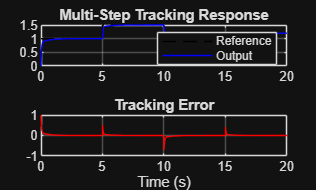

%% Problem 2: Complex Input Tracking
% Define Time Vector
t = 0:0.01:20;

% -- Task (a): Multi-Step Reference --
% Create reference signal
r_step = zeros(size(t));
r_step(t >= 0 & t < 5) = 1;
r_step(t >= 5 & t < 10) = 1.5;
r_step(t >= 10 & t < 15) = 0.8;
r_step(t >= 15) = 1.2;

% Simulate
[y_step, t_out] = lsim(Sys_pid, r_step, t);
error_step = r_step' - y_step;

figure;
subplot(2,1,1);
plot(t, r_step, 'k--', t, y_step, 'b');
title('Multi-Step Tracking Response');
legend('Reference', 'Output');
grid on;

subplot(2,1,2);
plot(t, error_step, 'r');
title('Tracking Error');
xlabel('Time (s)');
grid on;

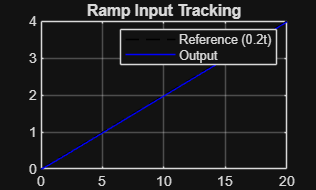


% -- Task (b): Ramp Input --
r_ramp = 0.2 * t;
[y_ramp, ~] = lsim(Sys_pid, r_ramp, t);
error_ramp = r_ramp' - y_ramp;

figure;
plot(t, r_ramp, 'k--', t, y_ramp, 'b');
title('Ramp Input Tracking');
legend('Reference (0.2t)', 'Output');
grid on;


% Calc steady state error (end of simulation)
ess_ramp = abs(error_ramp(end));
disp(['Ramp Steady State Error: ', num2str(ess_ramp)]);

Ramp Steady State Error: 0.025


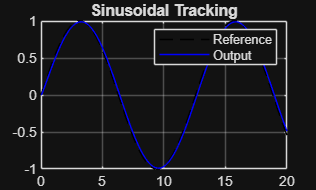


% -- Task (c): Sinusoidal Reference --
r_sine = sin(0.5 * t);
[y_sine, ~] = lsim(Sys_pid, r_sine, t);

figure;
plot(t, r_sine, 'k--', t, y_sine, 'b');
title('Sinusoidal Tracking');
legend('Reference', 'Output');
grid on;


% -- Manual Peak Finding (No Toolbox Required) --
% Ensure signals are column vectors for consistent processing
y_vec = y_sine(:);
r_vec = r_sine(:);
t_vec = t(:);

% Find indices where the current value is greater than both neighbors (a peak)
ref_idx = find(r_vec(2:end-1) > r_vec(1:end-2) & r_vec(2:end-1) > r_vec(3:end)) + 1;
out_idx = find(y_vec(2:end-1) > y_vec(1:end-2) & y_vec(2:end-1) > y_vec(3:end)) + 1;

% Get the time values for these peaks
locs_ref = t_vec(ref_idx);
locs_out = t_vec(out_idx);

% Calculate Lag using the last detected peak
if ~isempty(locs_ref) && ~isempty(locs_out)
    % Compare the last peak of reference to the last peak of output
    lag = locs_ref(end) - locs_out(end);
    disp(['Approximate Phase Lag (sec): ', num2str(abs(lag))]);
else
    disp('Peaks not found. Simulation time might be too short.');
end

Approximate Phase Lag (sec): 0.12



lag = locs_ref(end) - locs_out(end);
disp(['Approximate Phase Lag (sec): ', num2str(abs(lag))]);

Approximate Phase Lag (sec): 0.12


- **Why PID struggles with Ramp Tracking: **A standard PID controller introduces one integrator (Type-1 system). To track a ramp input (which is the integral of a step) with zero steady-state error, the system requires two integrators (Type-2). Because our loop only has one integrator, it can track the *slope* of the ramp but will always trail behind by a constant finite error, known as the velocity error.

- **Which parameter affects sinusoidal tracking:**The **Proportional Gain **and **Integral Gain** primarily affect the bandwidth. Increasing bandwidth reduces phase lag at lower frequencies (like 0.5 rad/s). However, the **Derivative **term adds phase lead, which directly counteracts phase lag, improving tracking accuracy for changing signals like sine waves.

Problem 3: Practical Implementation Challenges

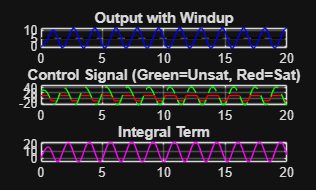

%% Problem 3: Practical Implementation Challenges
% Plant: G(s) = 50 / (s^3 + 8s^2 + 25s + 20)
num = 50;
den = [1 8 25 20];
G3 = tf(num, den);

% Simulation Parameters
dt = 0.01;
T_sim = 20;
t = 0:dt:T_sim;
u_lim = 10;

% Discretize Plant for Manual Loop Simulation
Gd = c2d(G3, dt, 'zoh');
[Ad, Bd, Cd, Dd] = ssdata(Gd); % State space matrices

% -- Task (a): Integral Windup (No Anti-Windup) --
Kp = 5; Ki = 8;
r = 5 * ones(size(t)); % Step input to 5

% Initialize vectors
y_windup = zeros(size(t));
u_windup = zeros(size(t));
u_unsat_log = zeros(size(t));
integral_term = zeros(size(t));
x = zeros(3,1); % Initial states
e_int = 0; % Integral accumulator

for k = 1:length(t)
    % Measurement
    y_windup(k) = Cd * x;
    
    % Error
    e = r(k) - y_windup(k);
    
    % PID Calculation (PI only for this part)
    u_p = Kp * e;
    e_int = e_int + e * dt; % Normal integration
    u_i = Ki * e_int;
    
    u_calc = u_p + u_i;
    u_unsat_log(k) = u_calc;
    
    % Saturation
    u_windup(k) = max(min(u_calc, u_lim), -u_lim);
    
    % Log integral term
    integral_term(k) = u_i;
    
    % Update Plant State
    x = Ad * x + Bd * u_windup(k);
end

figure;
subplot(3,1,1); plot(t, r, 'k--', t, y_windup, 'b'); title('Output with Windup'); grid on;
subplot(3,1,2); plot(t, u_windup, 'r', t, u_unsat_log, 'g--'); title('Control Signal (Green=Unsat, Red=Sat)'); grid on;
subplot(3,1,3); plot(t, integral_term, 'm'); title('Integral Term'); grid on;

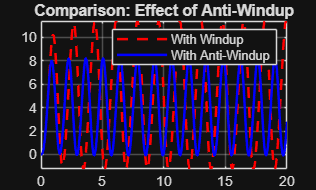



% -- Task (b): Anti-Windup (Back-Calculation) --
Kt = sqrt(Ki); % Tracking gain
y_anti = zeros(size(t));
u_anti = zeros(size(t));
x = zeros(3,1); 
e_int = 0;

for k = 1:length(t)
    y_anti(k) = Cd * x;
    e = r(k) - y_anti(k);
    
    % Standard PID terms
    u_p = Kp * e;
    u_i = Ki * e_int;
    
    u_calc = u_p + u_i;
    u_sat = max(min(u_calc, u_lim), -u_lim);
    
    % Back-Calculation for Integral Update
    % If u_calc != u_sat, we subtract the difference to stop integrating
    e_int = e_int + (e + (u_sat - u_calc)/Kt) * dt;
    
    u_anti(k) = u_sat;
    
    % Update Plant
    x = Ad * x + Bd * u_anti(k);
end

figure;
plot(t, y_windup, 'r--', t, y_anti, 'b', 'LineWidth', 1.5);
legend('With Windup', 'With Anti-Windup');
title('Comparison: Effect of Anti-Windup');
grid on;

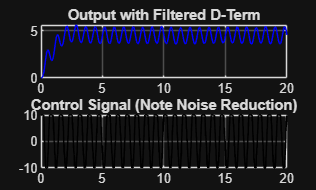



% -- Task (c): Derivative Noise & Filtering --
Kd = 2;
tau = 0.1;
alpha = tau / (tau + dt); % Filter coefficient
y_noise = zeros(size(t));
u_filt = zeros(size(t));
x = zeros(3,1); 
e_int = 0;
prev_ed_filt = 0;

% Define Noisy Measurement
noise = 0.05 * randn(size(t));

for k = 1:length(t)
    % Plant output + Noise
    y_clean = Cd * x;
    y_meas = y_clean + noise(k);
    y_noise(k) = y_clean; % Log actual position
    
    e = r(k) - y_meas;
    
    % P Term
    u_p = Kp * e;
    
    % I Term (with Anti-Windup)
    u_i = Ki * e_int;
    
    % D Term with Low Pass Filter
    % Filter the error for derivative: e_d_filt(k) = alpha*prev + (1-alpha)*e
    ed_filt = alpha * prev_ed_filt + (1 - alpha) * e;
    
    % Derivative is slope of FILTERED error
    % (Or standard derivative filtered, here we use band-limited diff)
    u_d = Kd * (ed_filt - prev_ed_filt) / dt;
    prev_ed_filt = ed_filt;
    
    % Total Control
    u_calc = u_p + u_i + u_d;
    u_sat = max(min(u_calc, u_lim), -u_lim);
    
    % Update Integral (Back Calc)
    e_int = e_int + (e + (u_sat - u_calc)/Kt) * dt;
    
    u_filt(k) = u_sat;
    x = Ad * x + Bd * u_filt(k);
end

figure;
subplot(2,1,1); plot(t, y_noise, 'b'); title('Output with Filtered D-Term'); grid on;
subplot(2,1,2); plot(t, u_filt, 'k'); title('Control Signal (Note Noise Reduction)'); grid on;



% -- Task (d): Complex Trajectory Tracking --
% Construct complex reference r(t)
r_complex = zeros(size(t));
for k = 1:length(t)
    ti = t(k);
    if ti < 2
        r_complex(k) = 0.5 * ti;
    elseif ti < 4
        r_complex(k) = 1;
    elseif ti < 8
        r_complex(k) = 1 + 0.5 * sin(2*pi*(ti - 4));
    elseif ti < 10
        r_complex(k) = 2; % Step up (assuming hold 1.5 -> 2, instructions ambiguous, using step to 2)
    elseif ti < 15
        r_complex(k) = 2 - 0.3 * (ti - 10);
    else
        r_complex(k) = 0.5;
    end
end

% Run Simulation with full controller (Anti-Windup + Filter)
y_comp = zeros(size(t));
u_comp = zeros(size(t));
x = zeros(3,1);
e_int = 0;
ed_filt = 0; 
prev_ed_filt = 0;

for k = 1:length(t)
    y_clean = Cd * x;
    e = r_complex(k) - y_clean;
    
    u_p = Kp * e;
    u_i = Ki * e_int;
    
    ed_filt = alpha * prev_ed_filt + (1 - alpha) * e;
    u_d = Kd * (ed_filt - prev_ed_filt) / dt;
    prev_ed_filt = ed_filt;
    
    u_calc = u_p + u_i + u_d;
    u_sat = max(min(u_calc, u_lim), -u_lim);
    
    e_int = e_int + (e + (u_sat - u_calc)/Kt) * dt;
    
    u_comp(k) = u_sat;
    y_comp(k) = y_clean;
    x = Ad * x + Bd * u_sat;
end

% RMS Error
error_comp = r_complex' - y_comp; % transpose if needed
rms_error = sqrt(mean(error_comp.^2));
disp(['RMS Tracking Error: ', num2str(rms_error)]);

RMS Tracking Error: 1.1218      1.1218      1.1218      1.1218      1.1218      1.1218      1.1217      1.1215      1.1213       1.121      1.1205      1.1199      1.1191      1.1182       1.117      1.1156      1.1139      1.1119      1.1097      1.1071      1.1042       1.101      1.0975      1.0935      1.0893      1.0846      1.0796      1.0743      1.0686      1.0626      1.0563      1.0496      1.0427      1.0355       1.028      1.0203      1.0125      1.0045     0.99629     0.98802     0.97968      0.9713     0.96292     0.95458     0.94629     0.93811     0.93005     0.92216     0.91446     0.90697     0.89974     0.89279     0.88613     0.87978     0.87378     0.86813     0.86284     0.85794     0.85341     0.84928     0.84555     0.84221     0.83926      0.8367     0.83452      0.8327     0.83124     0.83012     0.82932     0.82882     0.82859     0.82862     0.82888     0.82933     0.82995      0.8307     0.83155     0.83246      0.8334     0.83433     0.83522     0.83602  

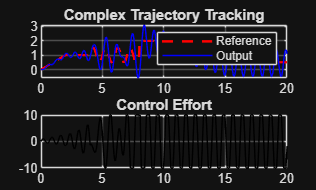


figure;
subplot(2,1,1);
plot(t, r_complex, 'r--', 'LineWidth', 1.5); hold on;
plot(t, y_comp, 'b');
title('Complex Trajectory Tracking');
legend('Reference', 'Output');
grid on;

subplot(2,1,2);
plot(t, u_comp, 'k');
title('Control Effort');
grid on;

- **Integral Windup Observation: **When the large step input is applied, the error is large, causing the Proportional and Integral terms to calculate a control signal much larger than the actuator limit (10V). While the actual input to the plant is clipped at 10V, the integrator continues to sum up the error (which stays large because the plant is responding slowly due to the limit). This causes the integral term to "wind up" to a huge value. When the plant finally reaches the setpoint, the integral term is still huge, keeping the control signal saturated positive effectively forcing the system to overshoot significantly until the error becomes negative long enough to "unwind" the integrator.

- **How Anti-Windup Helps: **The back-calculation method modifies the integral update rule. When the actuator saturates, the difference is negative. This negative value is fed back into the integrator, effectively stopping or reducing the accumulation of error during saturation. This ensures that as soon as the plant output reaches the reference, the integrator is ready to respond immediately, preventing the massive overshoot observed in the part above.

- **Role of Filtering: **Pure derivative action amplifies high-frequency signals. Noise is typically high-frequency, so a pure derivative controller creates violent oscillations in the control signal even if the output looks smooth. The Low-Pass Filter reduces the gain at high frequencies, smoothing out the noise before the derivative is calculated, preventing actuator wear while preserving the damping effect on the main system dynamics.